Data is imported from the  **COVID-19 Data Repository by the Center for Systems Science and Engineering (CSSE) at Johns Hopkins University**. The Beta and Vega parameters are approximated by using the the timeframe before appropriate measures to "flatten the curve" were put into place; this is detect by calculating the 30 days leading to a peak in cases. 

confirmed = loadData('confirmed')

confirmed = 266×186 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36

deaths = loadData('deaths')

deaths = 266×186 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36   

recovered = loadData('recovered')

recovered = 253×186 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36


region = 12; % Queensland
t = 12:width(confirmed) 

t =     12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61


qlpop = 5072000; 

s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t};
i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t};
r1 = deaths{region,t} + recovered{region,t};

M = transpose([s1; i1; r1])

M =      5071999           1           0
     5071997           3           0
     5071998           2           0
     5071997           3           0
     5071998           2           0
     5071998           2           0
     5071997           3           0
     5071997           3           0
     5071996           4           0
     5071995           5           0



[b, v] = betaVegaCalc((confirmed{region,t}), (deaths{region,t}), (recovered{region,t}), 80, 30);

Once the data is sufficiently loaded, a quick plot was used to ensure the complete and accurate data is being used.

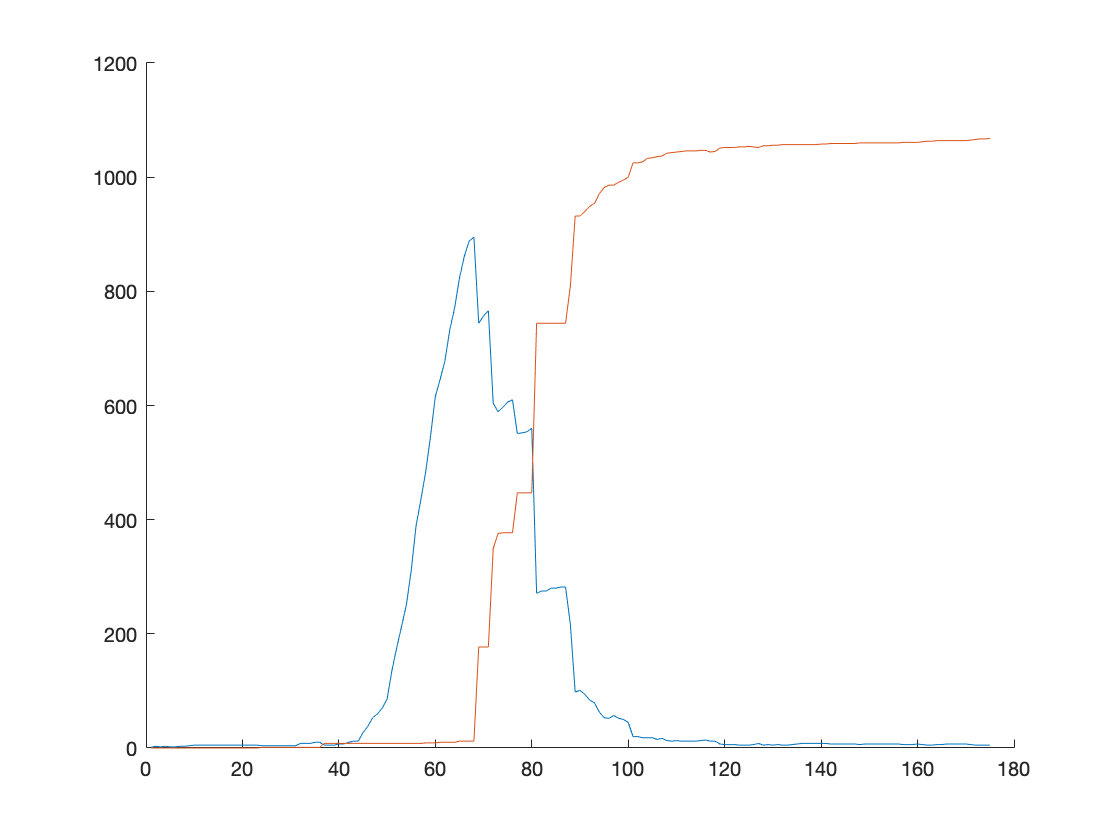

figure
hold on
%plot(5072000-confirmed{region,t}-deaths{region,t}-recovered{region,t})
plot(confirmed{region,t}-deaths{region,t}-recovered{region,t})
plot(deaths{region,t}+recovered{region,t})

[pks, locs] = findpeaks(confirmed{region,t}-deaths{region,t}-recovered{region,t})

pks =      3     3     5    10   895   766   610   560   282   101    57    17    13    14     8     6     6     8     7     7     7


locs =      2     4    10    35    68    71    76    80    86    90    97   107   110   116   127   129   131   136   149   160   166


In order to calculate $R_0$, the Jacobian matrix representing the rates of change amongst all the comparments (Susceptible, Infected, and Recovered) are calculated. Epidimiologist utilized this matrix to determine the rate of change produced by a single infected individual; this is accomplished by utilized the eigenvalues. The spectrul radius, or dominant eigenvalue, ends up becoming the rate of infection from a single infection. 

br = 0;

u = 1 - v;
t=20;

s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t}

s1 = 5071996

i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t}

i1 = 4

r1 = deaths{region,t} + recovered{region,t}

r1 = 0

M =      5071996           4           0


J = [-b(t)*i1-u(t) -b(t)*s1 0; b(t)*i1 b(t)*s1-v(t)-u(t) 0; 0 v(t) -u(t)];
J

J = 	1.0e+06 *

   -0.0000   -5.1606         0
    0.0000    5.1606         0
         0         0   -0.0000


[V,D] = eig(J)

V =    -1.0000    0.7071         0
    0.0000   -0.7071         0
         0         0    1.0000


D = 	1.0e+06 *

   -0.0000         0         0
         0    5.1606         0
         0         0   -0.0000


V =     1.0000   -0.7071         0
         0    0.7071         0
         0         0    1.0000


D = 	1.0e+06 *

   -0.0000         0         0
         0    8.0208         0
         0         0   -0.0000


qlpop = 5072000

d1 = 12

s1 = 5071999

i1 = 1

r1 = 0

g1 =      5071999           1           0


d2 = 50

s2 = 5071979

i2 = 5

r2 = 8

g2 =      5071979           5           8


M =     1.0000   -0.0000         0
         0   -0.6000    1.0000
         0         0    1.0000
